## Gabriel Werpel Fernandes

## July 2024

## Load Data

% Close all figures and clear variables
clc;
close all;
clearvars;

%Process EEG Data
data = processAllEEGData();

Data for file A1_Full_Block.bdf processed successfully
Data for file A3_Full_Block.bdf processed successfully
Data for file A4_Full_Block.bdf processed successfully
Data for file A6_Alpha.bdf processed successfully
Data for file A8_Alpha.bdf processed successfully
Data for file A9_Alpha.bdf processed successfully
Data for file C12_Alpha.bdf processed successfully
Data for file C13_Alpha.bdf processed successfully
Data for file C15_Alpha.bdf processed successfully
Data for file C1_Alpha.bdf processed successfully


## Plot Time-Series

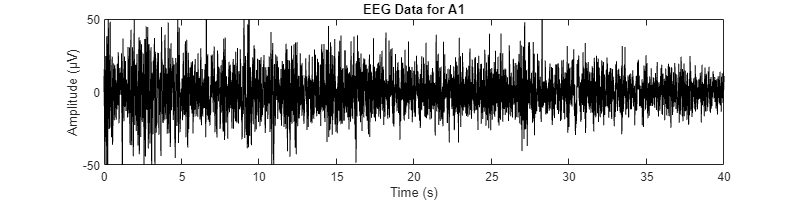

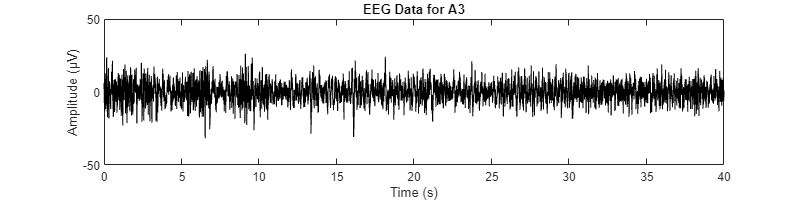

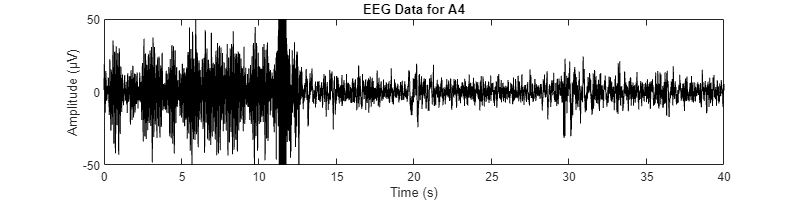

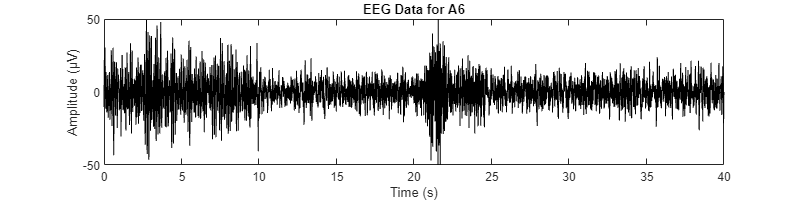

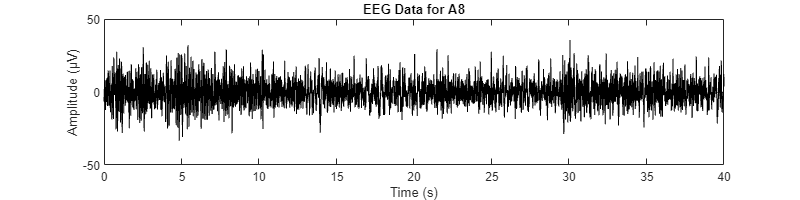

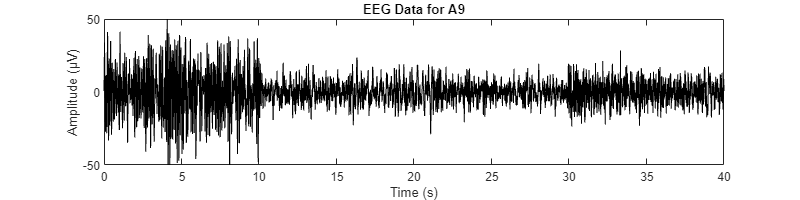

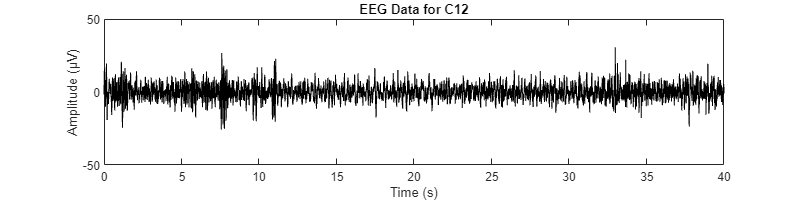

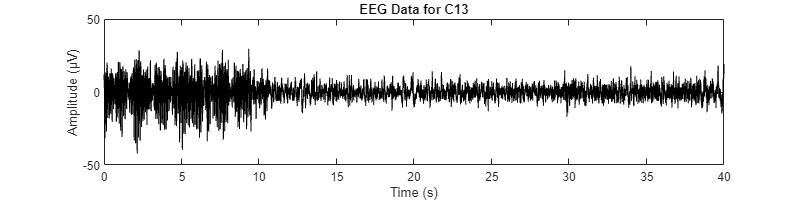

% Plot all EEG data
plotAllEEGData(data);

## Segment Data

% Segment the EEG data
segmentedData = segmentEEGDataNew(data);

## Compute and Plot Fourier Spectrum

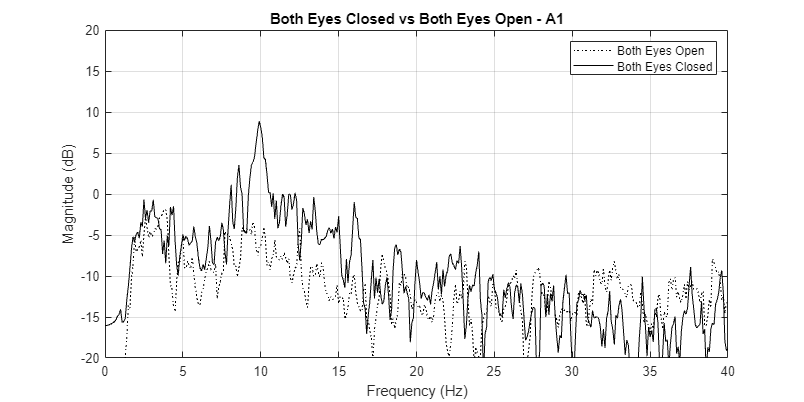

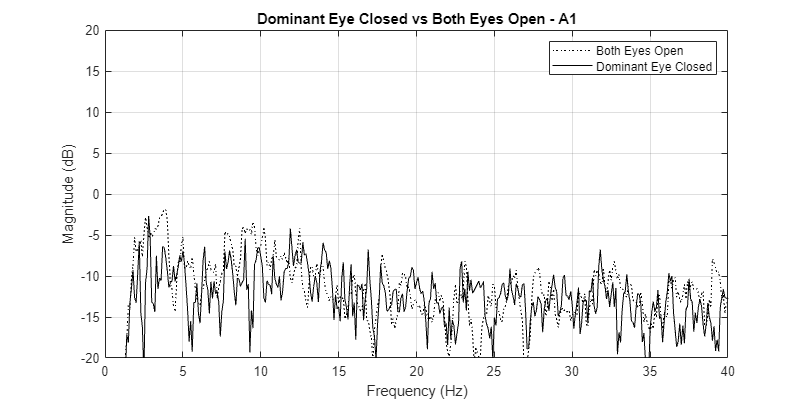

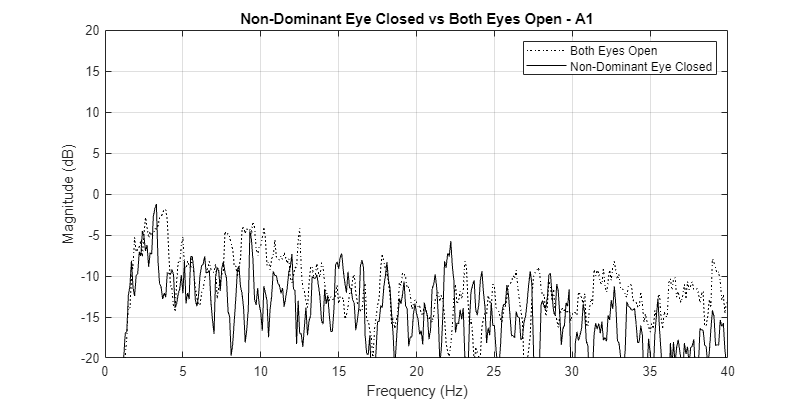

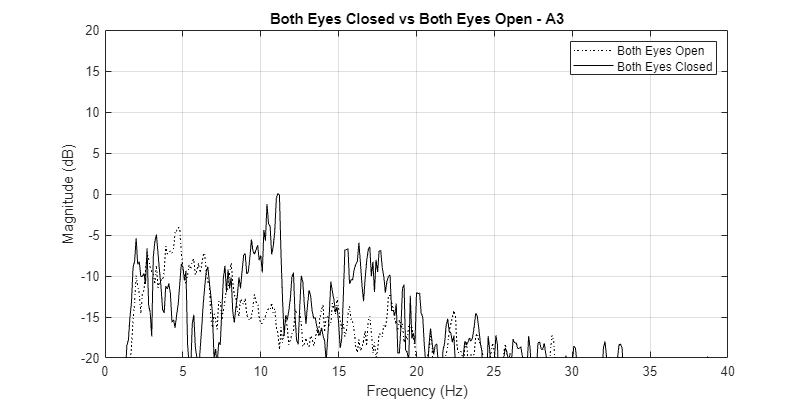

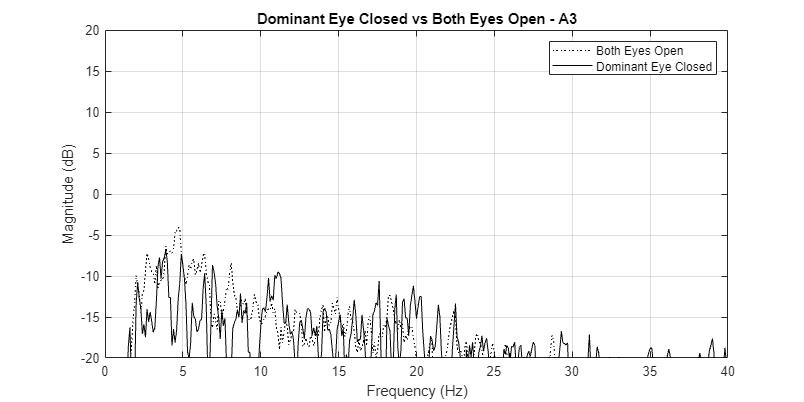

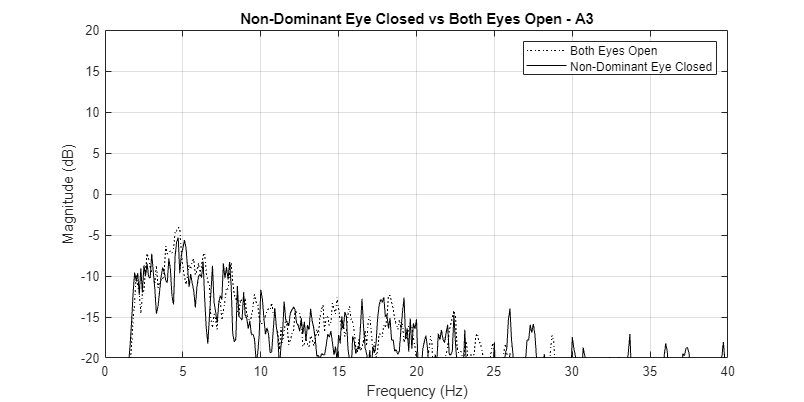

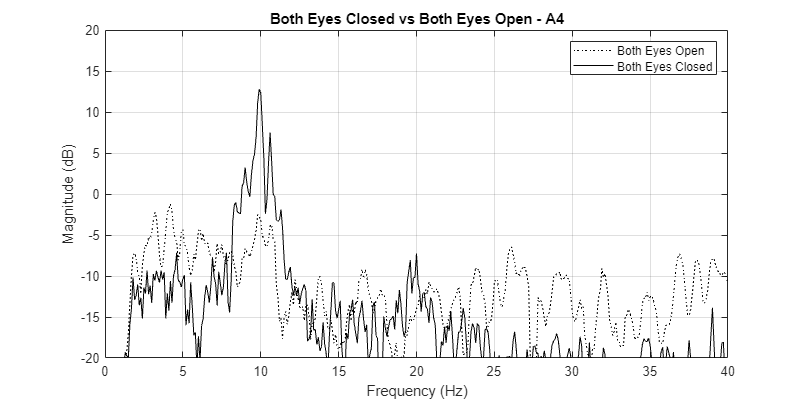

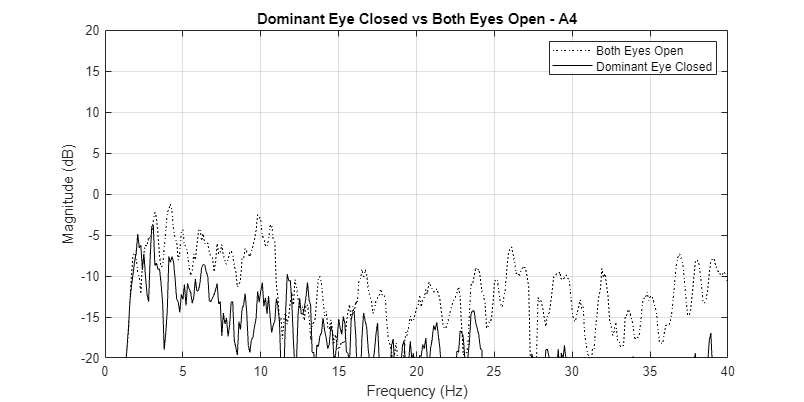

% Compute and plot the Fourier spectra, and get the spectra results
spectraResults = plotAndComputeFourierSpectra(segmentedData);

## Reactivity

% Compute the reactivity and other metrics
reactivityResults = computeReactivity(spectraResults);

Key: A1
Max Power EC: 11.62 dB at 10.0 Hz
Max Power EO: -0.25 dB at 10.1 Hz
--- Reactivity EO-EC: -11.87 dB ---
Max Power DEC: -0.68 dB at 8.9 Hz
Max Power EO: -1.71 dB at 8.9 Hz
--- Reactivity EO-DEC: -1.03 dB ---
Max Power NDEC: -3.57 dB at 9.4 Hz
Max Power EO: -1.31 dB at 9.5 Hz
--- Reactivity EO-NDEC: 2.27 dB ---

Key: A3
Max Power EC: 2.19 dB at 10.3 Hz
Max Power EO: -11.56 dB at 10.3 Hz
--- Reactivity EO-EC: -13.75 dB ---
Max Power DEC: -7.20 dB at 11.2 Hz
Max Power EO: -8.18 dB at 11.5 Hz
--- Reactivity EO-DEC: -0.98 dB ---
Max Power NDEC: -7.98 dB at 10.1 Hz
Max Power EO: -9.95 dB at 9.7 Hz
--- Reactivity EO-NDEC: -1.98 dB ---

Key: A4
Max Power EC: 14.46 dB at 9.9 Hz
Max Power EO: -0.02 dB at 10.0 Hz
--- Reactivity EO-EC: -14.48 dB ---
Max Power DEC: -4.71 dB at 11.8 Hz
Max Power EO: -5.92 dB at 12.0 Hz
--- Reactivity EO-DEC: -1.21 dB ---
Max Power NDEC: -7.36 dB at 8.6 Hz
Max Power EO: -3.84 dB at 8.2 Hz
--- Reactivity EO-NDEC: 3.52 dB ---

Key: A6
Max Power EC: 11.98 dB at 8

showAllReactivities(reactivityResults)

Key                  EC-EO (dB)      DEC-EO (dB)     NDEC-EO (dB)   
----------------------------------------------------------------------
A1                   -11.87          -1.03           2.27           
A3                   -13.75          -0.98           -1.98          
A4                   -14.48          -1.21           3.52           
A6                   -18.26          -3.87           -5.96          
A8                   -14.51          -2.03           -2.00          
A9                   -18.32          -5.62           -1.02          
C12                  -6.33           2.24            3.32           
C13                  -21.97          0.04            3.66           
C15                  -13.78          -0.21           3.70           
C1                   -13.30          0.51            -1.37          


calculateReactivityPValues(reactivityResults)

P-value between EC-EO and DEC-EO: 0.000000
P-value between EC-EO and NDEC-EO: 0.000000
P-value between DEC-EO and NDEC-EO: 0.214634


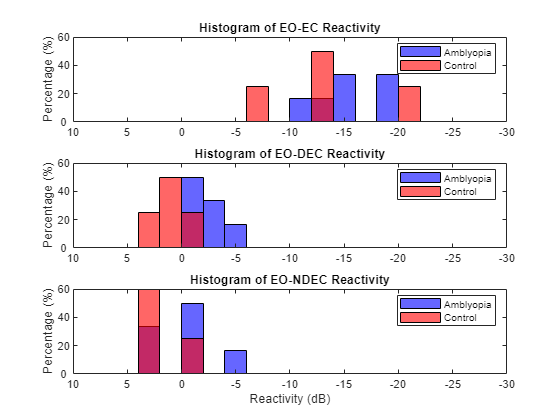

plotReactivityHistogram(reactivityResults)

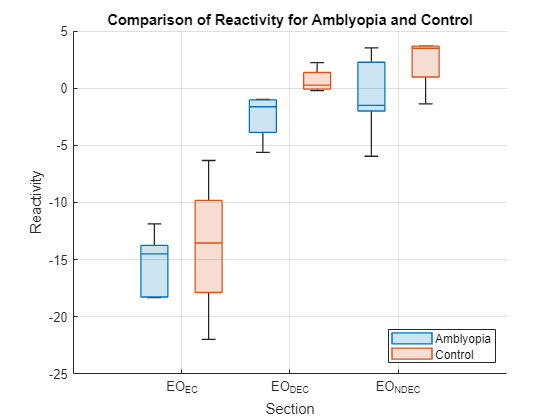

plotReactivityBoxPlots(reactivityResults, 'Reactivity', 'Reactivity')

calculateReactivityGroupPValues(reactivityResults)

P-value between A and C groups for EC-EO: 0.647440
P-value between A and C groups for DEC-EO: 0.019168
P-value between A and C groups for NDEC-EO: 0.147357


## Bandwidth

% Define the dB drop for bandwidth calculation
dB_drop = 3;

% Compute the bandwidth for all segmented data
bandwidthResults = computeBandwidth(spectraResults, dB_drop);

Unrecognized field name "BE_Closed_spectrum_dB".

Error in computeBandwidth (line 13)
        BE_Closed_spectrum_dB = data.BE_Closed_spectrum_dB;

## Coherence

% Define parameters for mscohere
% window = 256;     % Window size for coherence calculation
% noverlap = 128;   % Number of overlapping samples
% nfft = 512;       % Number of FFT points

window = []; %2048;     % Window size for coherence calculation
noverlap = []; % 2048/2;   % Number of overlapping samples
nfft = [];       % Number of FFT points

% Calculate and plot coherence for BE_Closed segments
coherenceResults = calculateAndPlotCoherence(segmentedData, window, noverlap, nfft);


## Skewness and Kurtosis

% Calculate the skewness and kurtosis for the alpha band of the Fourier distributions
alphaStatsResults = calculateAlphaStats(spectraResults);

## PSD - (Power Spectral Density) Welch's Method

% Define parameters for pwelch
window = [];%2048;     % Window size for PSD calculation
noverlap = [];%2028/2;   % Number of overlapping samples
nfft = [];       % Number of FFT points

% Compute and plot PSD for BE_Closed segments
psdResults = computeAndPlotPSD(segmentedData, window, noverlap, nfft);

## PSD - Skewness and Kurtosis

% Calculate the skewness and kurtosis for the alpha band of the PSD distributions
alphaStatsResultsPSD = calculateAlphaStatsFromPSD(psdResults);

## PSD - Power, Frequency and Reactivity

% Compute the reactivity and other metrics from PSD
psdReactivityResults = computePSDReactivity(psdResults, dB_drop);

## PSD - Bandwidth

% Compute the bandwidth for all segmented data from PSD
psdBandwidthResults = computePSDBandwidth(psdResults, dB_drop);

## Data Analysis

% Assuming 'psdReactivityResults', 'alphaStatsResults', 'psdBandwidthResults', and 'psdCoherenceResults'
% are the structures returned by the respective functions
%psdReactivityResults = computePSDReactivity(psdResults, dB_drop);
%alphaStatsResults = calculateAlphaStatsFromPSD(psdResults);
%psdBandwidthResults = computePSDBandwidth(psdResults, dB_drop);
%CoherenceResults = calculateAndPlotCoherence(segmentedData, window, noverlap, nfft);

% Perform hypothesis tests comparing A* and C* data
hypothesisTestResults = performHypothesisTests(psdReactivityResults, alphaStatsResults, psdBandwidthResults, CoherenceResults);

% Assuming 'psdReactivityResults', 'alphaStatsResults', 'psdBandwidthResults', and 'psdCoherenceResults'
% are the structures returned by the respective functions
psdReactivityResults


function hypothesisTestResults = performHypothesisTests(psdReactivityResults, alphaStatsResults, psdBandwidthResults, psdCoherenceResults)
    % Initialize the hypothesis test results structure
    hypothesisTestResults = struct;

    % Separate keys into A* and C* groups
    A_keys = {};
    C_keys = {};
    fields = fieldnames(psdReactivityResults);
    for i = 1:numel(fields)
        key = fields{i};
        if startsWith(key, 'A')
            A_keys{end+1} = key;
        elseif startsWith(key, 'C')
            C_keys{end+1} = key;
        end
    end

    % Ensure we have both A* and C* keys
    if isempty(A_keys) || isempty(C_keys)
        error('Both A* and C* groups must have data.');
    end

    % Helper function to extract values and perform t-tests
    function [p, A_values, C_values] = ttest2groups(dataStruct, fieldName)
        A_values = [];
        C_values = [];
        for k = 1:numel(A_keys)
            if isfield(dataStruct.(A_keys{k}), fieldName)
                A_values = [A_values; dataStruct.(A_keys{k}).(fieldName)];
            end
        end
        for k = 1:numel(C_keys)
            if isfield(dataStruct.(C_keys{k}), fieldName)
                C_values = [C_values; dataStruct.(C_keys{k}).(fieldName)];
            end
        end
        [~, p] = ttest2(A_values, C_values);
    end

    % Reactivity and max closed-open diff tests
    [hypothesisTestResults.reactivity, reactivity_A, reactivity_C] = ttest2groups(psdReactivityResults, 'reactivity');
    [hypothesisTestResults.max_closed_open_diff, max_diff_A, max_diff_C] = ttest2groups(psdReactivityResults, 'max_closed_open_diff');

    % Bandwidth tests
    [hypothesisTestResults.bandwidth_closed, bandwidth_A, bandwidth_C] = ttest2groups(psdBandwidthResults, 'bandwidth_closed');

    % Alpha band skewness and kurtosis tests
    [hypothesisTestResults.skewness_BE_Closed, skewness_BE_Closed_A, skewness_BE_Closed_C] = ttest2groups(alphaStatsResults, 'skewness_BE_Closed');
    [hypothesisTestResults.kurtosis_BE_Closed, kurtosis_BE_Closed_A, kurtosis_BE_Closed_C] = ttest2groups(alphaStatsResults, 'kurtosis_BE_Closed');
    [hypothesisTestResults.skewness_BE_Open, skewness_BE_Open_A, skewness_BE_Open_C] = ttest2groups(alphaStatsResults, 'skewness_BE_Open');
    [hypothesisTestResults.kurtosis_BE_Open, kurtosis_BE_Open_A, kurtosis_BE_Open_C] = ttest2groups(alphaStatsResults, 'kurtosis_BE_Open');
    [hypothesisTestResults.skewness_LE_Closed, skewness_LE_Closed_A, skewness_LE_Closed_C] = ttest2groups(alphaStatsResults, 'skewness_LE_Closed');
    [hypothesisTestResults.kurtosis_LE_Closed, kurtosis_LE_Closed_A, kurtosis_LE_Closed_C] = ttest2groups(alphaStatsResults, 'kurtosis_LE_Closed');
    [hypothesisTestResults.skewness_RE_Closed, skewness_RE_Closed_A, skewness_RE_Closed_C] = ttest2groups(alphaStatsResults, 'skewness_RE_Closed');
    [hypothesisTestResults.kurtosis_RE_Closed, kurtosis_RE_Closed_A, kurtosis_RE_Closed_C] = ttest2groups(alphaStatsResults, 'kurtosis_RE_Closed');

    % Coherence tests
    function [p, A_values, C_values] = ttest2coherence(dataStruct, A_keys, C_keys)
        A_values = [];
        C_values = [];
        for i = 1:numel(A_keys)
            for j = 1:numel(C_keys)
                if isfield(dataStruct.(A_keys{i}), C_keys{j})
                    A_values = [A_values; dataStruct.(A_keys{i}).(C_keys{j}).coherence];
                end
                if isfield(dataStruct.(C_keys{j}), A_keys{i})
                    C_values = [C_values; dataStruct.(C_keys{j}).(A_keys{i}).coherence];
                end
            end
        end
        [~, p] = ttest2(A_values, C_values);
    end

    [hypothesisTestResults.coherence, coherence_A, coherence_C] = ttest2coherence(psdCoherenceResults, A_keys, C_keys);

    % Create a table of results
    metrics = {'Reactivity', 'Max Closed-Open Diff', 'Bandwidth Closed', ...
               'Skewness BE Closed', 'Kurtosis BE Closed', 'Skewness BE Open', 'Kurtosis BE Open', ...
               'Skewness LE Closed', 'Kurtosis LE Closed', 'Skewness RE Closed', 'Kurtosis RE Closed', ...
               'Coherence'};
    p_values = [hypothesisTestResults.reactivity, hypothesisTestResults.max_closed_open_diff, ...
                hypothesisTestResults.bandwidth_closed, hypothesisTestResults.skewness_BE_Closed, ...
                hypothesisTestResults.kurtosis_BE_Closed, hypothesisTestResults.skewness_BE_Open, ...
                hypothesisTestResults.kurtosis_BE_Open, hypothesisTestResults.skewness_LE_Closed, ...
                hypothesisTestResults.kurtosis_LE_Closed, hypothesisTestResults.skewness_RE_Closed, ...
                hypothesisTestResults.kurtosis_RE_Closed, hypothesisTestResults.coherence];

    significance = arrayfun(@(p) ifelse(p < 0.05, 'Significant', 'Not Significant'), p_values, 'UniformOutput', false);

    results_table = table(metrics', p_values', significance', 'VariableNames', {'Metric', 'p_value', 'Significance'});

    % Display the results table
    disp('Hypothesis Test Results:');
    disp(results_table);

    % Plot the comparisons
    figure;
    subplot(3, 4, 1);
    boxplot([reactivity_A, reactivity_C], 'Labels', {'A*', 'C*'});
    title('Reactivity');

    subplot(3, 4, 2);
    boxplot([max_diff_A, max_diff_C], 'Labels', {'A*', 'C*'});
    title('Max Closed-Open Diff');

    subplot(3, 4, 3);
    boxplot([bandwidth_A, bandwidth_C], 'Labels', {'A*', 'C*'});
    title('Bandwidth Closed');

    subplot(3, 4, 4);
    boxplot([skewness_BE_Closed_A, skewness_BE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Skewness BE Closed');

    subplot(3, 4, 5);
    boxplot([kurtosis_BE_Closed_A, kurtosis_BE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Kurtosis BE Closed');

    subplot(3, 4, 6);
    boxplot([skewness_BE_Open_A, skewness_BE_Open_C], 'Labels', {'A*', 'C*'});
    title('Skewness BE Open');

    subplot(3, 4, 7);
    boxplot([kurtosis_BE_Open_A, kurtosis_BE_Open_C], 'Labels', {'A*', 'C*'});
    title('Kurtosis BE Open');

    subplot(3, 4, 8);
    boxplot([skewness_LE_Closed_A, skewness_LE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Skewness LE Closed');

    subplot(3, 4, 9);
    boxplot([kurtosis_LE_Closed_A, kurtosis_LE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Kurtosis LE Closed');

    subplot(3, 4, 10);
    boxplot([skewness_RE_Closed_A, skewness_RE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Skewness RE Closed');

    subplot(3, 4, 11);
    boxplot([kurtosis_RE_Closed_A, kurtosis_RE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Kurtosis RE Closed');

    subplot(3, 4, 12);
    boxplot([coherence_A, coherence_C], 'Labels', {'A*', 'C*'});
    title('Coherence');
end

% Helper function for conditional string selection
function result = ifelse(condition, trueResult, falseResult)
    if condition
        result = trueResult;
    else
        result = falseResult;
    end
end


function hypothesisTestResults = performHypothesisTests2(psdReactivityResults, alphaStatsResults, psdBandwidthResults, psdCoherenceResults)
    % Initialize the hypothesis test results structure
    hypothesisTestResults = struct;

    % Separate keys into A* and C* groups
    A_keys = {};
    C_keys = {};
    fields = fieldnames(psdReactivityResults);
    for i = 1:numel(fields)
        key = fields{i};
        if startsWith(key, 'A')
            A_keys{end+1} = key;
        elseif startsWith(key, 'C')
            C_keys{end+1} = key;
        end
    end

    % Ensure we have both A* and C* keys
    if isempty(A_keys) || isempty(C_keys)
        error('Both A* and C* groups must have data.');
    end

    % Helper function to extract values and perform t-tests
    function p = ttest2groups(dataStruct, fieldName)
        A_values = [];
        C_values = [];
        for k = 1:numel(A_keys)
            if isfield(dataStruct.(A_keys{k}), fieldName)
                A_values = [A_values; dataStruct.(A_keys{k}).(fieldName)];
            end
        end
        for k = 1:numel(C_keys)
            if isfield(dataStruct.(C_keys{k}), fieldName)
                C_values = [C_values; dataStruct.(C_keys{k}).(fieldName)];
            end
        end
        [~, p] = ttest2(A_values, C_values);
    end

    % Reactivity and max closed-open diff tests
    hypothesisTestResults.reactivity = ttest2groups(psdReactivityResults, 'reactivity');
    hypothesisTestResults.max_closed_open_diff = ttest2groups(psdReactivityResults, 'max_closed_open_diff');

    % Bandwidth tests
    hypothesisTestResults.bandwidth_closed = ttest2groups(psdBandwidthResults, 'bandwidth_closed');

    % Alpha band skewness and kurtosis tests
    hypothesisTestResults.skewness_BE_Closed = ttest2groups(alphaStatsResults, 'skewness_BE_Closed');
    hypothesisTestResults.kurtosis_BE_Closed = ttest2groups(alphaStatsResults, 'kurtosis_BE_Closed');
    hypothesisTestResults.skewness_BE_Open = ttest2groups(alphaStatsResults, 'skewness_BE_Open');
    hypothesisTestResults.kurtosis_BE_Open = ttest2groups(alphaStatsResults, 'kurtosis_BE_Open');
    hypothesisTestResults.skewness_LE_Closed = ttest2groups(alphaStatsResults, 'skewness_LE_Closed');
    hypothesisTestResults.kurtosis_LE_Closed = ttest2groups(alphaStatsResults, 'kurtosis_LE_Closed');
    hypothesisTestResults.skewness_RE_Closed = ttest2groups(alphaStatsResults, 'skewness_RE_Closed');
    hypothesisTestResults.kurtosis_RE_Closed = ttest2groups(alphaStatsResults, 'kurtosis_RE_Closed');

    % Coherence tests
    function p = ttest2coherence(dataStruct, A_keys, C_keys)
        A_values = [];
        C_values = [];
        for i = 1:numel(A_keys)
            for j = 1:numel(C_keys)
                if isfield(dataStruct.(A_keys{i}), C_keys{j})
                    A_values = [A_values; dataStruct.(A_keys{i}).(C_keys{j}).coherence];
                end
                if isfield(dataStruct.(C_keys{j}), A_keys{i})
                    C_values = [C_values; dataStruct.(C_keys{j}).(A_keys{i}).coherence];
                end
            end
        end
        [~, p] = ttest2(A_values, C_values);
    end

    hypothesisTestResults.coherence = ttest2coherence(psdCoherenceResults, A_keys, C_keys);

    % Display the results with explanations
    disp('Hypothesis Test Results:');
    fprintf('Reactivity: p = %f\n', hypothesisTestResults.reactivity);
    if hypothesisTestResults.reactivity < 0.05
        disp('The reactivity between A* and C* groups is significantly different.');
    else
        disp('The reactivity between A* and C* groups is not significantly different.');
    end

    fprintf('Max Closed-Open Diff: p = %f\n', hypothesisTestResults.max_closed_open_diff);
    if hypothesisTestResults.max_closed_open_diff < 0.05
        disp('The maximum closed-open difference between A* and C* groups is significantly different.');
    else
        disp('The maximum closed-open difference between A* and C* groups is not significantly different.');
    end

    fprintf('Bandwidth (Closed): p = %f\n', hypothesisTestResults.bandwidth_closed);
    if hypothesisTestResults.bandwidth_closed < 0.05
        disp('The bandwidth for the closed condition between A* and C* groups is significantly different.');
    else
        disp('The bandwidth for the closed condition between A* and C* groups is not significantly different.');
    end

    fprintf('Skewness (BE Closed): p = %f\n', hypothesisTestResults.skewness_BE_Closed);
    if hypothesisTestResults.skewness_BE_Closed < 0.05
        disp('The skewness for BE Closed between A* and C* groups is significantly different.');
    else
        disp('The skewness for BE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Kurtosis (BE Closed): p = %f\n', hypothesisTestResults.kurtosis_BE_Closed);
    if hypothesisTestResults.kurtosis_BE_Closed < 0.05
        disp('The kurtosis for BE Closed between A* and C* groups is significantly different.');
    else
        disp('The kurtosis for BE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Skewness (BE Open): p = %f\n', hypothesisTestResults.skewness_BE_Open);
    if hypothesisTestResults.skewness_BE_Open < 0.05
        disp('The skewness for BE Open between A* and C* groups is significantly different.');
    else
        disp('The skewness for BE Open between A* and C* groups is not significantly different.');
    end

    fprintf('Kurtosis (BE Open): p = %f\n', hypothesisTestResults.kurtosis_BE_Open);
    if hypothesisTestResults.kurtosis_BE_Open < 0.05
        disp('The kurtosis for BE Open between A* and C* groups is significantly different.');
    else
        disp('The kurtosis for BE Open between A* and C* groups is not significantly different.');
    end

    fprintf('Skewness (LE Closed): p = %f\n', hypothesisTestResults.skewness_LE_Closed);
    if hypothesisTestResults.skewness_LE_Closed < 0.05
        disp('The skewness for LE Closed between A* and C* groups is significantly different.');
    else
        disp('The skewness for LE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Kurtosis (LE Closed): p = %f\n', hypothesisTestResults.kurtosis_LE_Closed);
    if hypothesisTestResults.kurtosis_LE_Closed < 0.05
        disp('The kurtosis for LE Closed between A* and C* groups is significantly different.');
    else
        disp('The kurtosis for LE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Skewness (RE Closed): p = %f\n', hypothesisTestResults.skewness_RE_Closed);
    if hypothesisTestResults.skewness_RE_Closed < 0.05
        disp('The skewness for RE Closed between A* and C* groups is significantly different.');
    else
        disp('The skewness for RE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Kurtosis (RE Closed): p = %f\n', hypothesisTestResults.kurtosis_RE_Closed);
    if hypothesisTestResults.kurtosis_RE_Closed < 0.05
        disp('The kurtosis for RE Closed between A* and C* groups is significantly different.');
    else
        disp('The kurtosis for RE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Coherence: p = %f\n', hypothesisTestResults.coherence);
    if hypothesisTestResults.coherence < 0.05
        disp('The coherence between A* and C* groups is significantly different.');
    else
        disp('The coherence between A* and C* groups is not significantly different.');
    end
end


